clear all; close all;

filename = 'spring_HiFi.wav'; 
CD_fs = 44100;
seconds = 10; 
samples = [1, seconds*CD_fs]; 
[y, Fs] = audioread(filename, samples);
info = audioinfo(filename)

info = struct with fields:
             Filename: 'C:\Users\Alexi\Documents\Alexis Iteso\9no semestre\Sistemas de Comunicaciones Digitales\spring_HiFi.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 44100
         TotalSamples: 736556
             Duration: 16.7020
                Title: 'Spring Mvt 1 Allegro'
              Comment: 'URL: http://freemusicarchive.org/music/John_Harrison_with_the_Wichita_State_University_Chamber_Players/The_Four_Seasons_Vivaldi/01_-_Vivaldi_Spring_mvt_1_Allegro_-_John_Harrison_violin_↵Comments: http://freemusicarchive.org/_↵Curator: Oddio Overplay_↵Copyright: Attribution-ShareAlike: http://creativecommons.org/licenses/by-sa/3.0/'
               Artist: 'John Harrison with the Wichita State University Chamber Players'
        BitsPerSample: 16


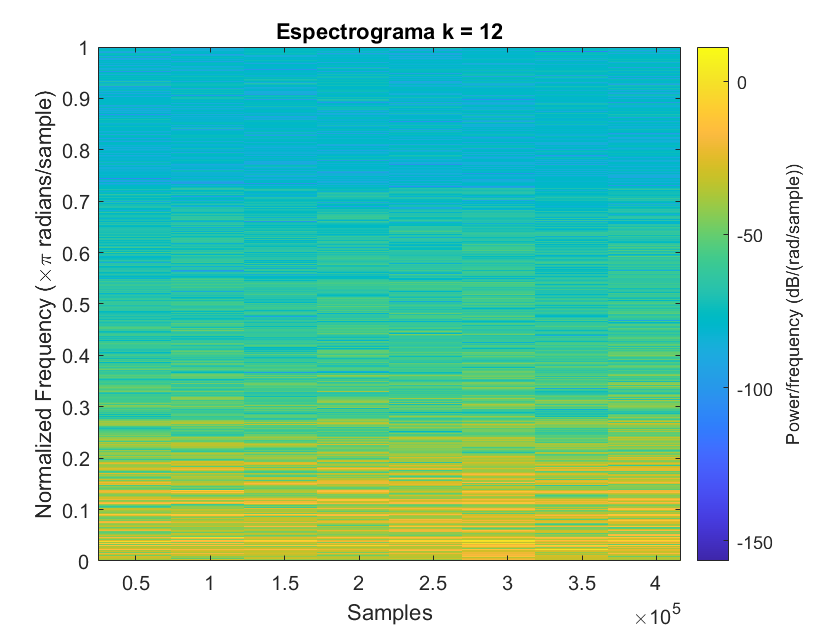

audiowrite('spring_HiFi_16b.wav', y, Fs)

% k = 12 bits
k = 12;
filename_12b = 'spring_HiFi_12b.wav';
swing = (2^k-1)/2; 
xq_int_12b = round(y*swing+swing);
xq_bin_12b = de2bi(xq_int_12b, k, 'left-msb');
xq_12b = (xq_int_12b-swing)/swing;
audiowrite(filename_12b, xq_12b, Fs)
spectrogram(xq_12b, 'yaxis');
title('Espectrograma k = 12')

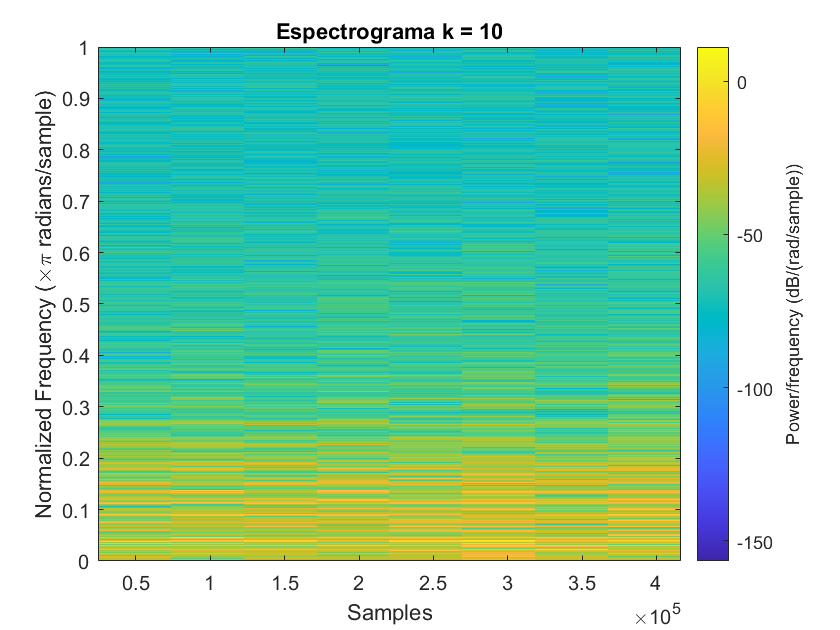


% k = 10 bits
k = 10;
filename_10b = 'spring_HiFi_10b.wav';
swing = (2^k-1)/2; 
xq_int_10b = round(y*swing+swing);
xq_bin_10b = de2bi(xq_int_10b, k, 'left-msb');
xq_10b = (xq_int_10b-swing)/swing;
audiowrite(filename_10b, xq_10b, Fs)
spectrogram(xq_10b, 'yaxis');
title('Espectrograma k = 10')

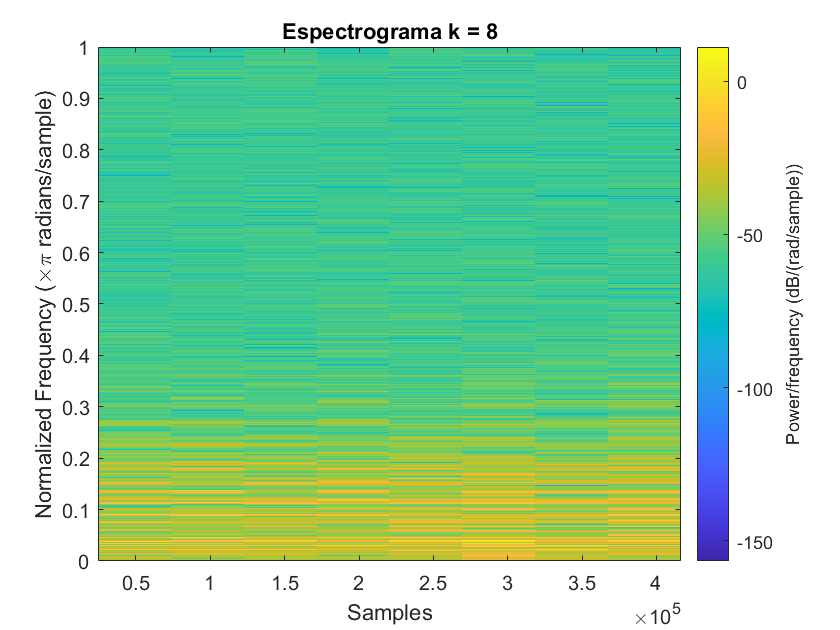


% k = 8 bits
k = 8;
filename_8b = 'spring_HiFi_8b.wav';
swing = (2^k-1)/2;
xq_int_8b = round(y*swing+swing);
xq_bin_8b = de2bi(xq_int_8b, k, 'left-msb');
xq_8b = (xq_int_8b-swing)/swing;
audiowrite(filename_8b, xq_8b, Fs)
spectrogram(xq_8b, 'yaxis');
title('Espectrograma k = 8')

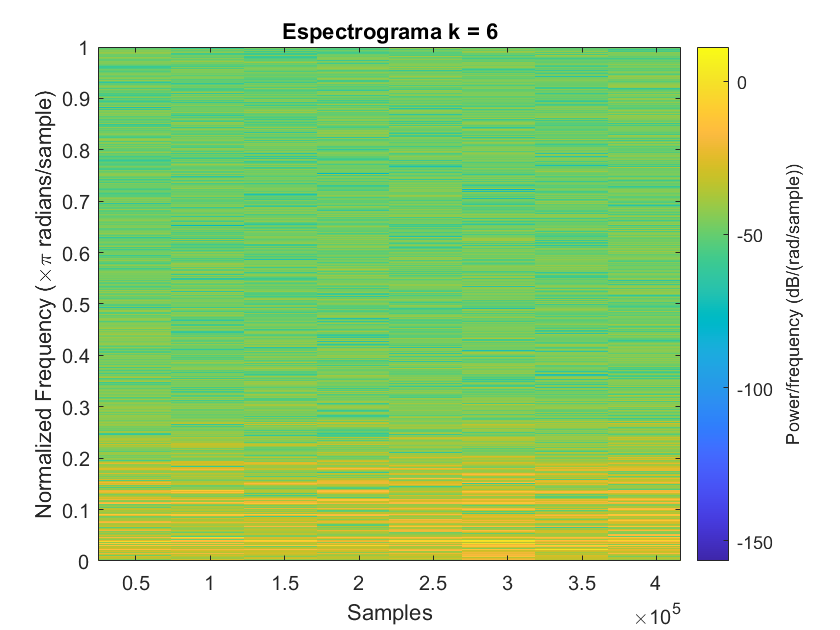


% k = 6 bits
k = 6;
filename_6b = 'spring_HiFi_6b.wav';
swing = (2^k-1)/2; 
xq_int_6b = round(y*swing+swing);
xq_bin_6b = de2bi(xq_int_6b, k, 'left-msb');
xq_6b = (xq_int_6b-swing)/swing;
audiowrite(filename_6b, xq_6b, Fs)
spectrogram(xq_6b, 'yaxis');
title('Espectrograma k = 6')

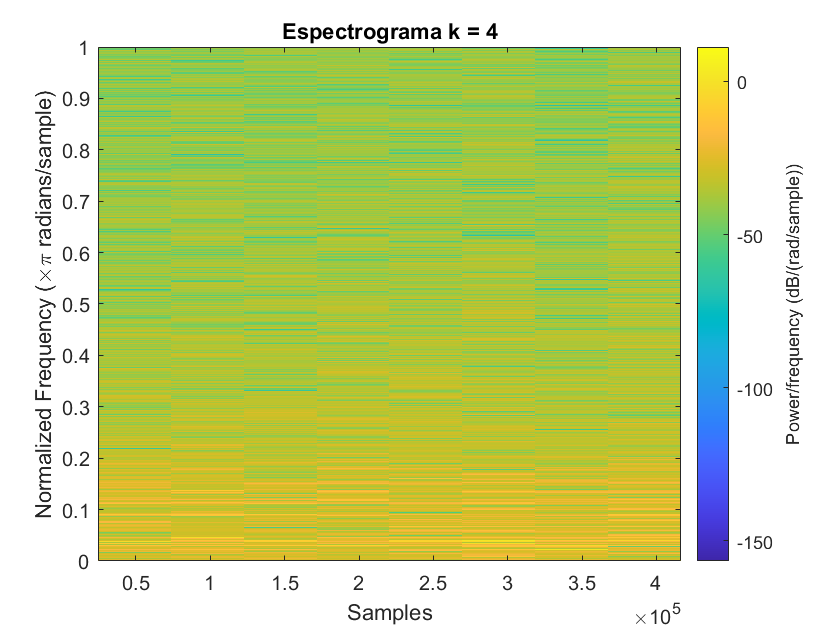


% k = 4 bits
k = 4;
filename_4b = 'spring_HiFi_4b.wav';
swing = (2^k-1)/2; 
xq_int_4b = round(y*swing+swing);
xq_bin_4b = de2bi(xq_int_4b, k, 'left-msb');
xq_4b = (xq_int_4b-swing)/swing;
audiowrite(filename_4b, xq_4b, Fs)
spectrogram(xq_4b, 'yaxis');
title('Espectrograma k = 4')

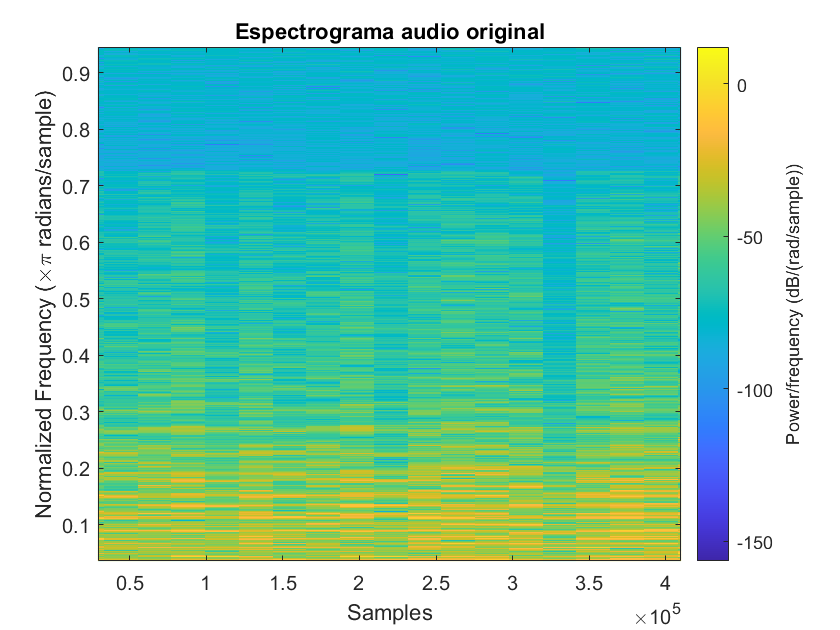

% Audio original
spectrogram(y, Fs, 'yaxis');
title('Espectrograma audio original');

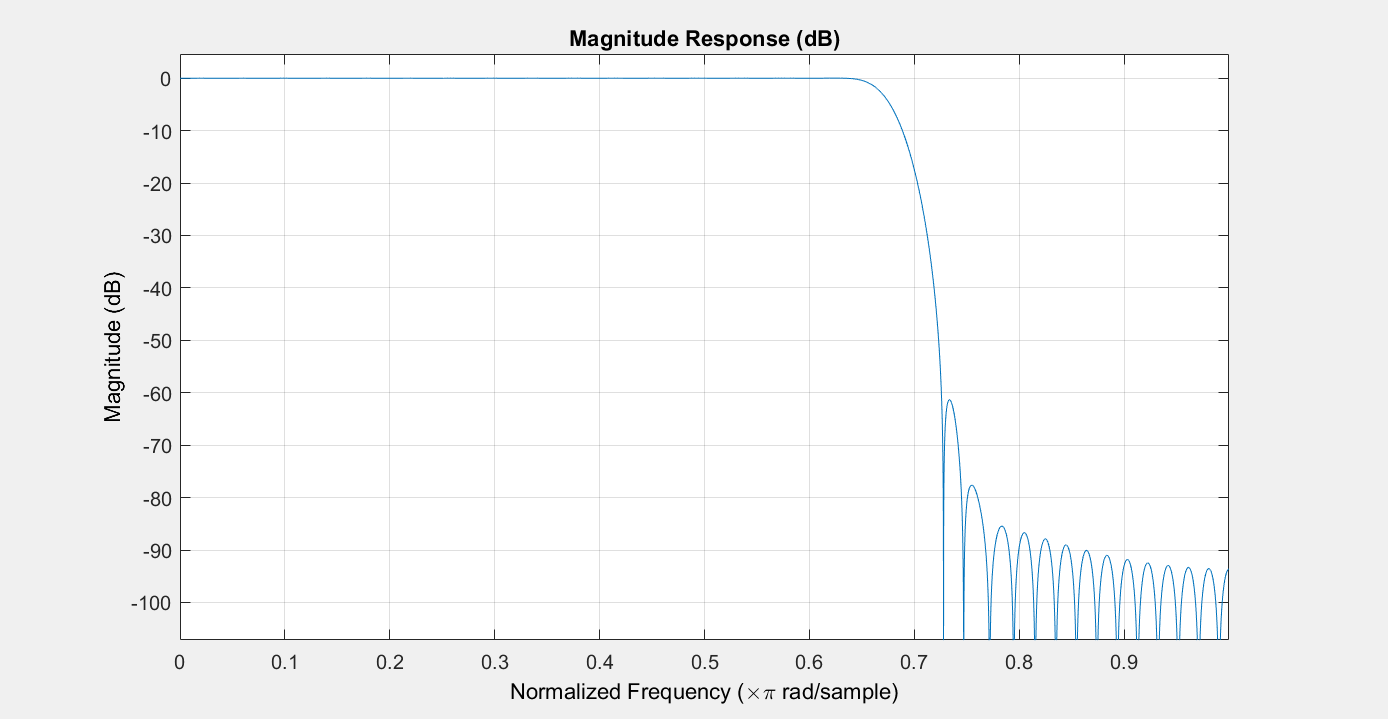

% Filtro de 15kHz
f = 15000;
f_filt_15k = 2*f/Fs; 
f_15k = [0, f_filt_15k, f_filt_15k, 1];
m_15k = [1 1 0 0];
b_15k = fir2(100, f_15k, m_15k);
fvtool(b_15k) %Espectro en frecuencia del filtro.

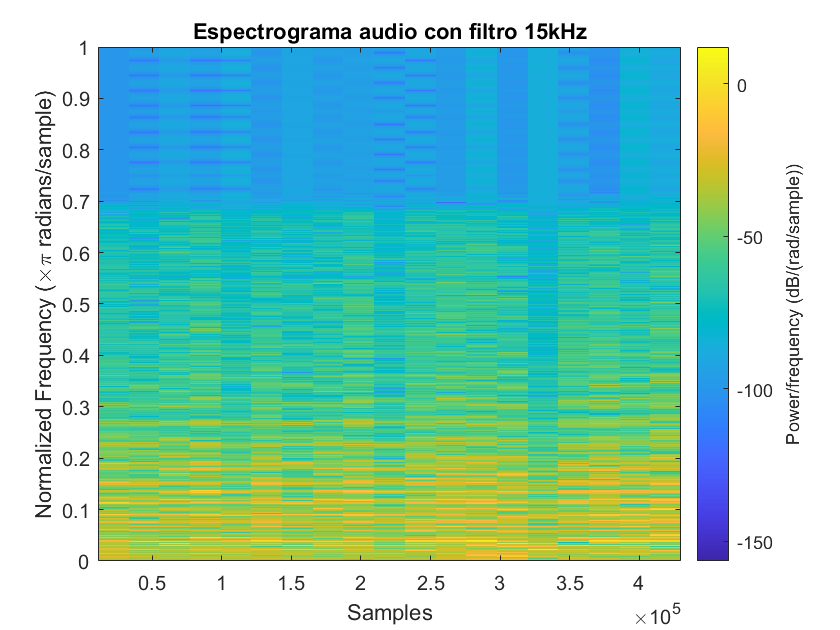

y_15k = conv(y, b_15k);
filename_Fltr15k = 'spring_HiFi_Fltr15k.wav';
audiowrite(filename_Fltr15k, y_15k, Fs)
spectrogram(y_15k, Fs, 'yaxis');
title('Espectrograma audio con filtro 15kHz');

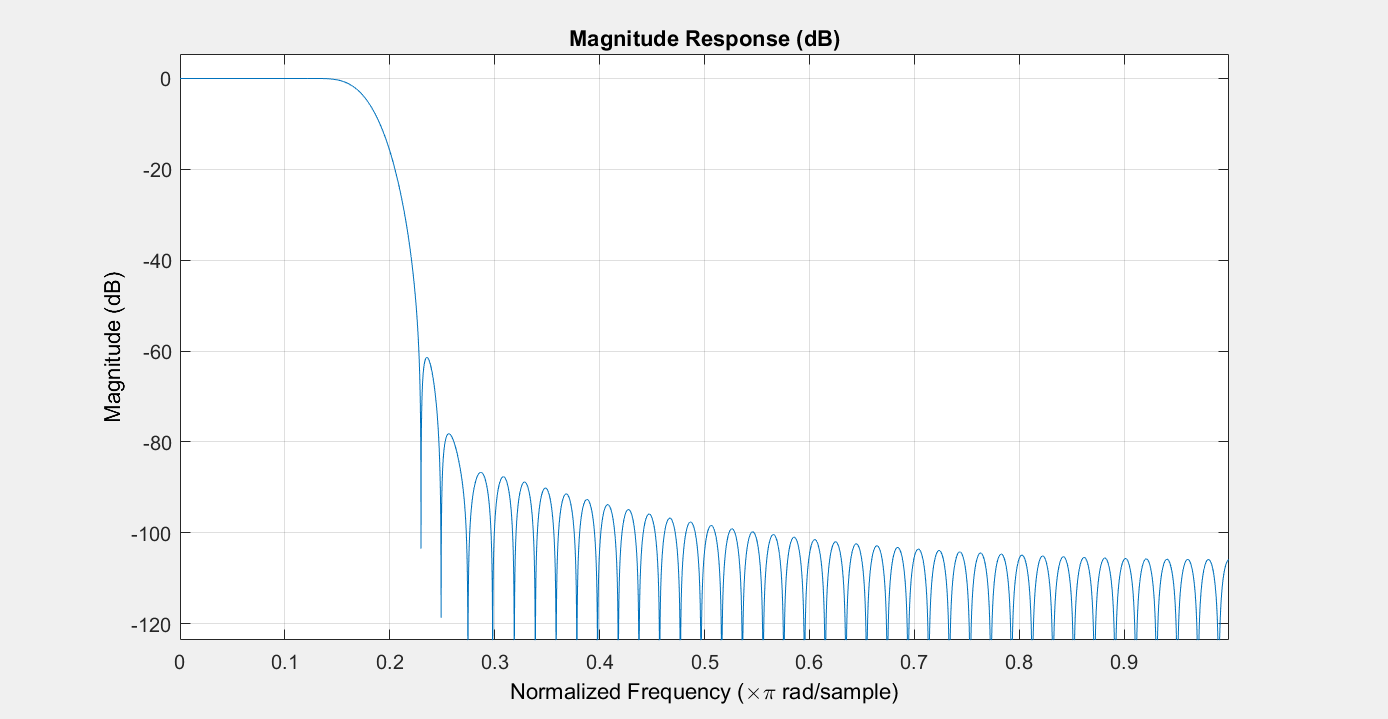

% Filtro de 4kHz
f = 4000;
f_filt_4k = 2*f/Fs; 
f_4k = [0, f_filt_4k, f_filt_4k, 1];
m_4k = [1 1 0 0];
b_4k = fir2(100, f_4k, m_4k);
fvtool(b_4k) 

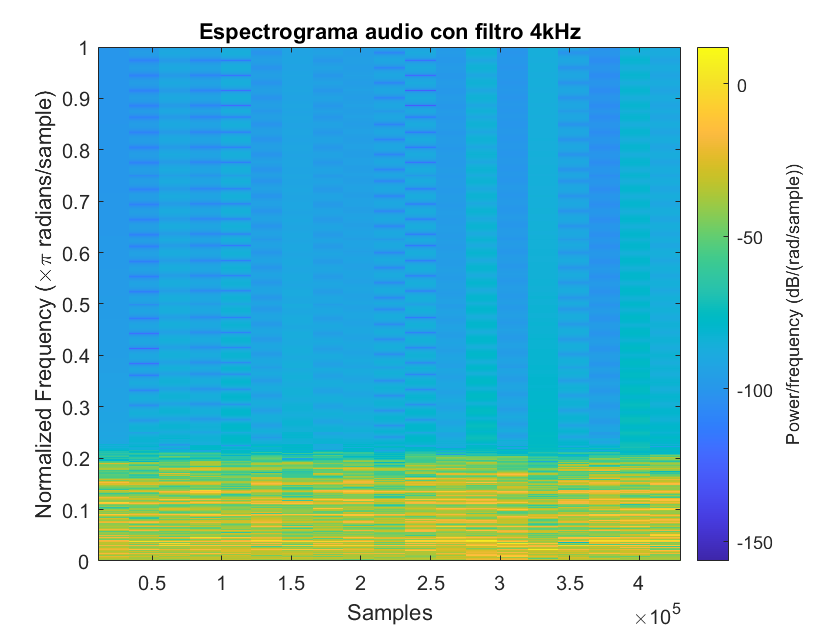

y_4k = conv(y, b_4k);
filename_Fltr4k = 'spring_HiFi_Fltr4k.wav';
audiowrite(filename_Fltr4k, y_4k, Fs)
spectrogram(y_4k, Fs, 'yaxis');
title('Espectrograma audio con filtro 4kHz');

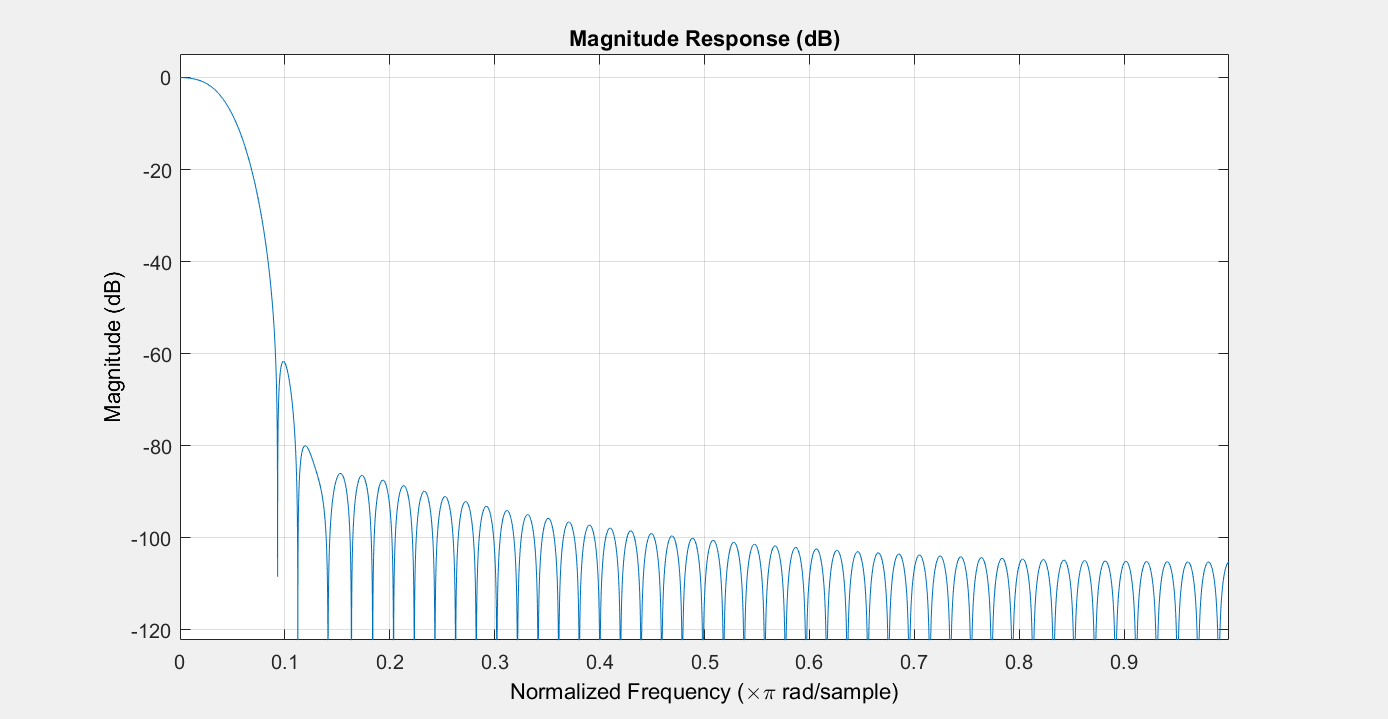

% Filtro de 1kHz
f = 1000;
f_filt_1k = 2*f/Fs; 
f_1k = [0, f_filt_1k, f_filt_1k, 1];
m_1k = [1 1 0 0];
b_1k = fir2(100, f_1k, m_1k);
fvtool(b_1k) 

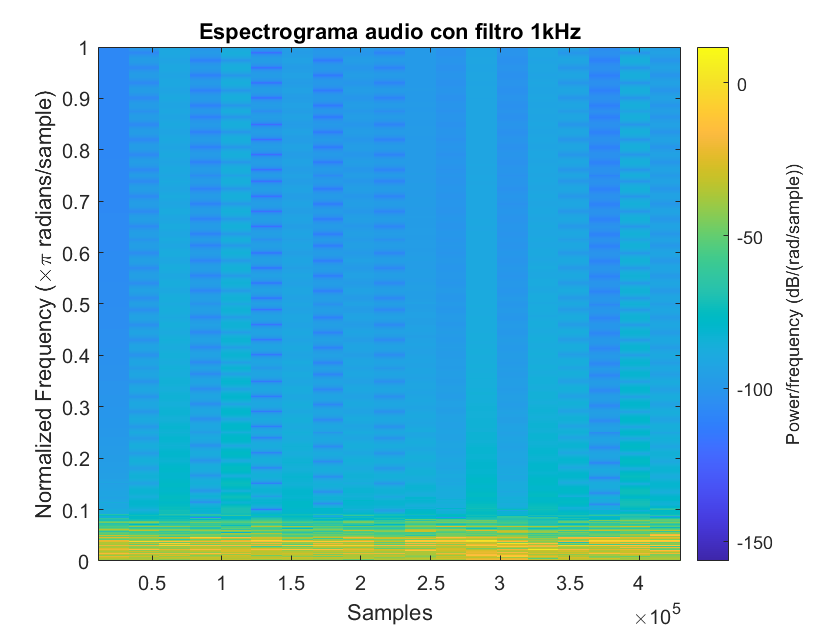

y_1k = conv(y, b_1k);
filename_Fltr1k = 'spring_HiFi_Fltr1k.wav';
audiowrite(filename_Fltr1k, y_1k, Fs)
spectrogram(y_1k, Fs, 'yaxis');
title('Espectrograma audio con filtro 1kHz');